Plotting script for the presentation

clear
clc
close all

cd 'C:\Users\ahmed\Torsobot\Modelling\2DRimlessWheel\dynamics_code\matlab'
addpath('C:\Users\ahmed\Torsobot\Modelling\torsobot_dynamics\matlab\plotting')

Import .mat file

load_file = load("./mat_files/solution_data.mat")

load_file = struct with fields:
    event_sol: [3×24 double]
        frame: 0
          sol: [3×1513 double]
        y_sol: [1×1 matlab.ode.ODEResults]



frames = load_file.frame;
t = load_file.sol(1, :);
ang = load_file.sol(2, :);
vel = load_file.sol(3, :);

parameters

% Wheel parameters (must match what was simulated)
slope_angle = deg2rad(2.5);
l = 0.4125;
n = 10;
collision_ang = pi/n;
slope_dist    = 2 * l * sin(pi/n);
epsilon = 1e-10;

Colors

color_torso_pos = [0.00, 0.45, 0.74];  % Dark Blue
color_torso_vel = [0.30, 0.75, 0.93];  % Light Blue
color_wheel_pos = [0.85, 0.33, 0.10];  % Dark Orange/Rust
color_wheel_vel = [0.93, 0.69, 0.13];  % Golden Orange
color_target    = [0.80, 0.20, 0.20];  % Muted Red for target ylines

Figures

fig1 = figure(1);
fig1.Units = 'pixels';
fig1.Position = [100, 100, 1600, 800];   % wide figure

tl = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- Left tile: spans 2 columns ---
ax1 = nexttile;
axis(ax1, 'off');

% --- Right tile: takes the remaining 1 column ---
ax2 = nexttile;
hold(ax2, 'on');

% static elements (drawn once, don't move)
xline(ax2, [-pi/10, pi/10], "--", 'Color', color_target, 'LineWidth', 1.5);
xlim(ax2, 0.33*[-1, 1]);
ylim(ax2, [min(vel)-0.05, max(vel)+0.05]);       % fix ylim so it doesn't jump
xlabel(ax2, "Wheel Position (rad)");
ylabel(ax2, 'Wheel Velocity (rad/s)');
grid(ax2, 'on');

% scatter handle — starts empty, grows each frame
h_scatter = scatter(ax2, NaN, NaN, 40, NaN, 'o', 'filled', ...
    'MarkerEdgeColor', [0.15 0.15 0.15], ...
    'MarkerFaceAlpha', 0.8, ...
    'LineWidth', 0.5);

colormap(ax2, 'parula');
ax2.FontSize = 14;
xlabel(ax2, "Wheel Position (rad)", 'FontSize', 16);
ylabel(ax2, 'Wheel Velocity (rad/s)', 'FontSize', 16);
clim(ax2, [min(t), max(t)]);           % fix color range so colors are stable
cb = colorbar(ax2);
cb.Label.String = 'Time (s)';
cb.Label.FontSize = 12;

plot animation

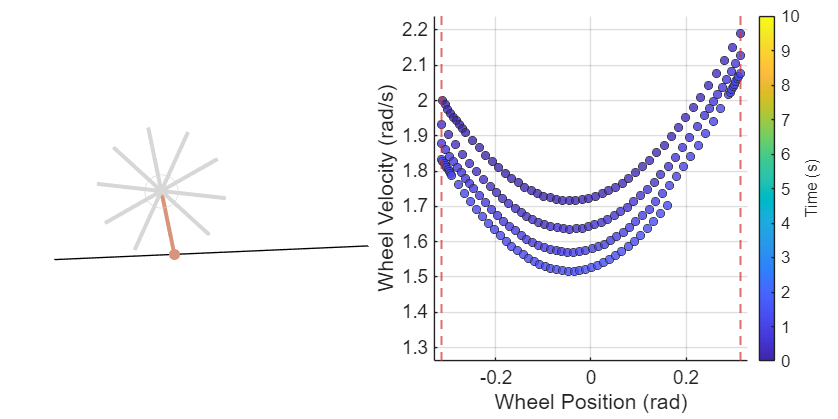

p_contact      = [0, 0];
gif_filename   = 'wheel_animation.gif';
mp4_filename   = 'wheel_animation.mp4';
dt_frame       = [diff(t), 0];

% Playback timing
playback_speed = 0.05;      % <1 = slower than real-time (0.7 ≈ 30% slower)
fps            = 30;       % video frame rate
dt_playback    = 1 / fps;

% Set up MP4 writer
v = VideoWriter(mp4_filename, 'MPEG-4');
v.FrameRate = fps;
v.Quality   = 95;
open(v);

for i = 1:200
    % --- left tile: draw wheel directly ---
    if vel(i) > 0 && abs(ang(i) - collision_ang) < epsilon
        p_contact = p_contact - [cos(slope_angle), sin(slope_angle)] * slope_dist;
        wheelPlot(ax1, slope_angle, l, n, t(i), -ang(i), p_contact);
    elseif vel(i) < 0 && abs(ang(i) - collision_ang) < epsilon
        p_contact = p_contact + [cos(slope_angle), sin(slope_angle)] * slope_dist;
        wheelPlot(ax1, slope_angle, l, n, t(i),  ang(i), p_contact);
    else
        wheelPlot(ax1, slope_angle, l, n, t(i),  ang(i), p_contact);
    end

    % --- right tile: update scatter ---
    h_scatter.XData = ang(1:i);
    h_scatter.YData = vel(1:i);
    h_scatter.CData = t(1:i);

    drawnow;
    frame_img = getframe(fig1);

    % --- write GIF frame with variable delay ---
    [A, map] = rgb2ind(frame_img.cdata, 256, 'nodither');
    delay    = max(dt_frame(i) / playback_speed, 0.02);

    if i == 1
        imwrite(A, map, gif_filename, 'gif', ...
                'LoopCount', Inf, 'DelayTime', delay);
    else
        imwrite(A, map, gif_filename, 'gif', ...
                'WriteMode', 'append', 'DelayTime', delay);
    end

    % --- write MP4 frames (repeat to match the same timing) ---
    n_repeats = max(1, round(dt_frame(i) / playback_speed / dt_playback));
    for k = 1:n_repeats
        writeVideo(v, frame_img);
    end
end


close(v);

State-time

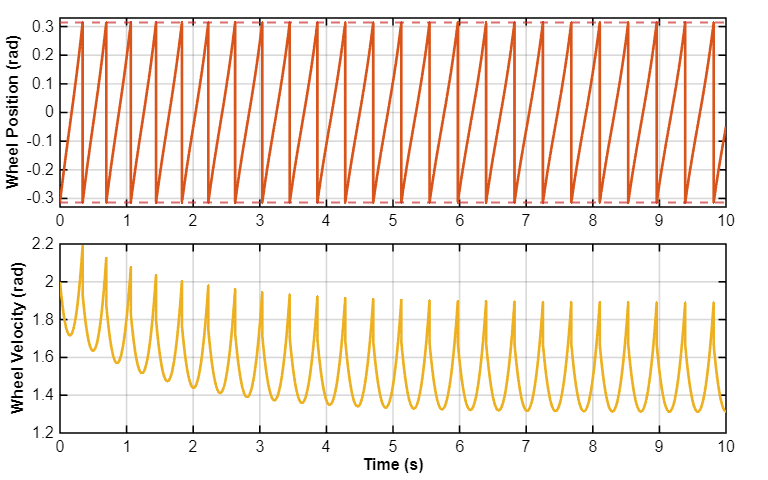

f2 = figure(2);

tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
plot(t, ang, 'Color', color_wheel_pos, 'LineWidth', 2);
hold on;
yline([pi/10, -pi/10], "--", 'Color', color_target, 'LineWidth',1.5);

ylim([-0.33, 0.33]);
xlim auto

ylabel("Wheel Position (rad)");

grid on;

hold off;

nexttile;
plot(t, vel, 'Color', color_wheel_vel, 'LineWidth', 2);
hold on;


ylim auto;
xlim auto

ylabel("Wheel Velocity (rad)");
xlabel("Time (s)");

grid on;

hold off;
format_my_plot(8, 5)

save_directory  = ".\";
save_filename = save_directory + "wheel_state.png";

exportgraphics(gcf, save_filename, 'Resolution', 600);